# Projeto - META 1

## 1. Configurações Iniciais e Criação da Tabela de Metadados


caminho = "data/36";
arquivos = dir(fullfile(caminho, "*.wav"));
nomesArquivos = {arquivos.name}';
pastasArquivos = {arquivos.folder}';
nArquivos = numel(nomesArquivos);

% Cria a tabela inicial com diretório e nome do arquivo
tab = table(pastasArquivos, nomesArquivos, 'VariableNames', {'Diretorio_Audio','Nome_Arquivo'});


% Extrai informações dos nomes dos arquivos (formato: digito_participante_repeticao.ext)
digitos = zeros(nArquivos,1);
participantes = zeros(nArquivos,1);
repeticoes = zeros(nArquivos,1);
for i = 1:nArquivos
    info = extrairInfoArquivo(tab.Nome_Arquivo{i});
    digitos(i) = info.digito;
    participantes(i) = info.participante;
    repeticoes(i) = info.repeticao;
end
tab.Digito = digitos;
tab.Participante = participantes;
tab.Repeticao = repeticoes;
disp(tab)

                        Diretorio_Audio                         Nome_Arquivo      Digito    Participante    Repeticao
    _______________________________________________________    _______________    ______    ____________    _________

    {'/Users/gcsilva/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_0.wav' }      0            36             0    
    {'/Users/gcsilva/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_1.wav' }      0            36             1    
    {'/Users/gcsilva/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_10.wav'}      0            36            10    
    {'/Users/gcsilva/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_11.wav'}      0            36            11    
    {'/Users/gcsilva/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_12.wav'}      0            36            12    
   

## 2. Carregamento dos Arquivos de Áudio (Sinais Brutos)

taxasAmostragem = zeros(nArquivos,1);
sinaisRaw = cell(nArquivos,1);
for i = 1:nArquivos
    caminhoArquivo = fullfile(tab.Diretorio_Audio{i}, tab.Nome_Arquivo{i});
    [s, fs] = audioread(caminhoArquivo);
    sinaisRaw{i} = s;
    taxasAmostragem(i) = fs;
end
tab.Taxa_Amostragem_Raw = taxasAmostragem;
tab.Sinal_Raw = sinaisRaw;

disp(tab)

                        Diretorio_Audio                         Nome_Arquivo      Digito    Participante    Repeticao    Taxa_Amostragem_Raw       Sinal_Raw    
    _______________________________________________________    _______________    ______    ____________    _________    ___________________    ________________

    {'/Users/gcsilva/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_0.wav' }      0            36             0               48000           {38637×1 double}
    {'/Users/gcsilva/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_1.wav' }      0            36             1               48000           {36217×1 double}
    {'/Users/gcsilva/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_10.wav'}      0            36            10    

## 3. Visualização dos Sinais Pré-processados

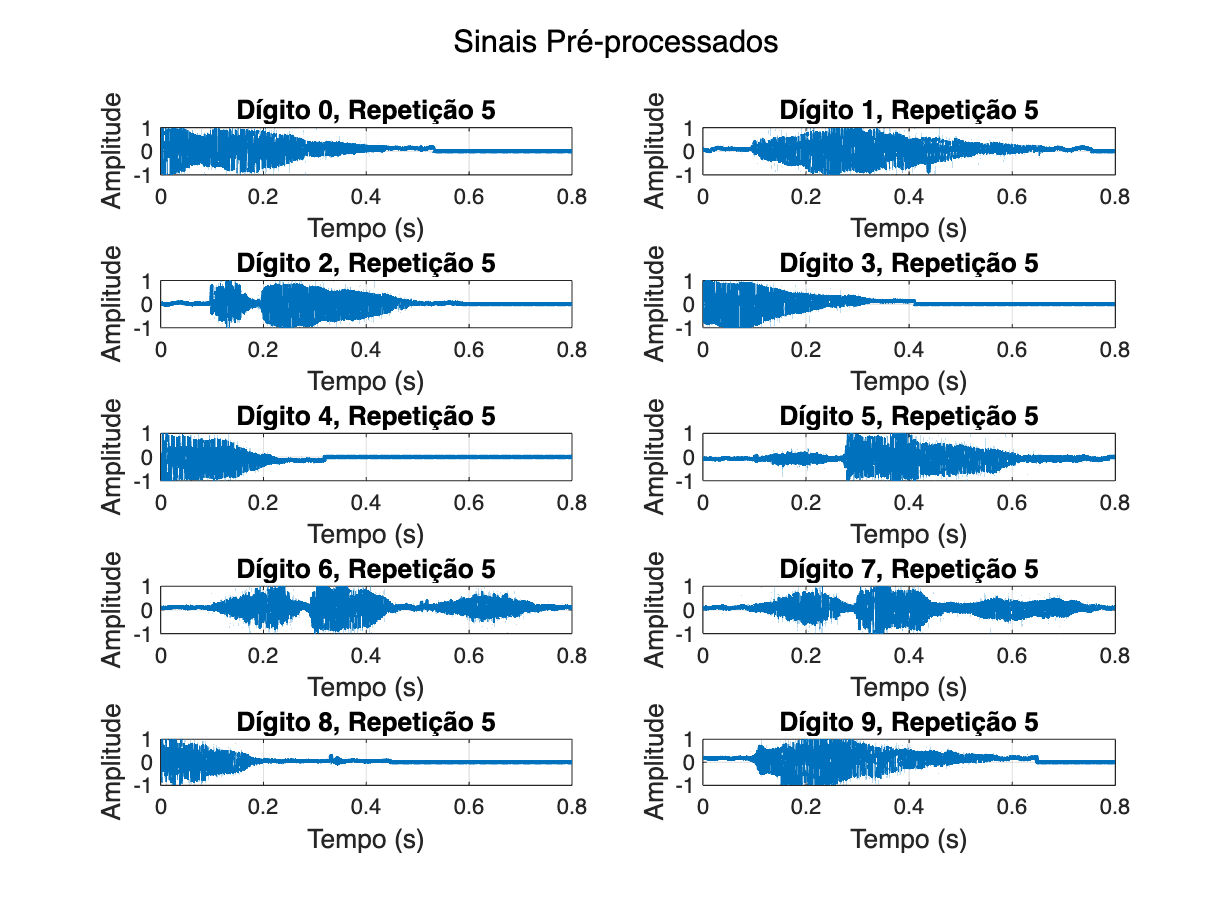

for i = 1:numDigitos
    digitoAtual = digitosUnicos(i);
    T_atual = T_filtro(T_filtro.Digito == digitoAtual, :);
    % Seleciona o primeiro arquivo para o dígito atual
    sinal = T_atual.Sinal_Processado{1};
    fs = T_atual.Taxa_Amostragem(1);
    t = (0:length(sinal)-1) / fs;
    subplot(numLinhas, numColunas, i);
    plot(t, sinal, 'LineWidth',2);
    title(sprintf('Dígito %d, Repetição %d', digitoAtual, repEscolhida), 'FontSize',12);
    xlabel('Tempo (s)', 'FontSize',12);
    ylabel('Amplitude', 'FontSize',12);
    grid on;
end
sgtitle('Sinais Pré-processados','FontSize',14);

## 4. Processamento dos Sinais de Áudio


% (remoção de silêncio, normalização e ajuste de duração para 0.8 segundos)
sinaisProc = cell(nArquivos,1);
for i = 1:nArquivos
    s = tab.Sinal_Raw{i};
    fs = tab.Taxa_Amostragem_Raw(i);
    sinaisProc{i} = processarSinal(s, fs);
end
tab.Sinal_Processado = sinaisProc;
% Como a taxa de amostragem não é alterada, podemos replicar a coluna original
tab.Taxa_Amostragem = taxasAmostragem;

## 5. Visualização dos Sinais Processados

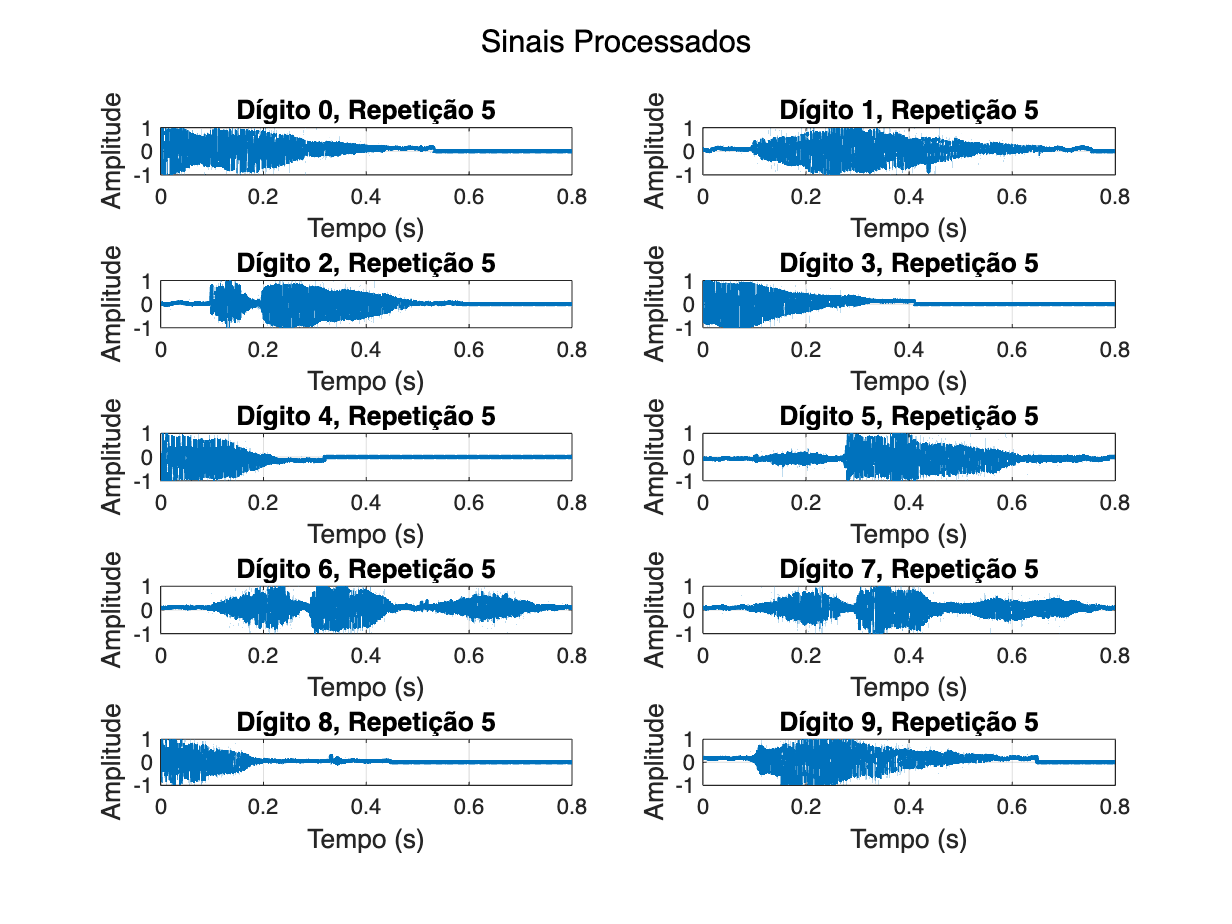

repEscolhida = 5;
T_filtro = tab(tab.Repeticao == repEscolhida, :);
if isempty(T_filtro)
    error('Nenhum arquivo encontrado para a repetição %d.', repEscolhida);
end

digitosUnicos = unique(T_filtro.Digito);
numDigitos = numel(digitosUnicos);
figure('Name', sprintf('Sinais Processados - Repetição %d', repEscolhida), 'NumberTitle','off');
numColunas = 2;
numLinhas = ceil(numDigitos / numColunas);
for i = 1:numDigitos
    digitoAtual = digitosUnicos(i);
    T_atual = T_filtro(T_filtro.Digito == digitoAtual, :);
    % Seleciona o primeiro arquivo para o dígito atual
    sinal = T_atual.Sinal_Processado{1};
    fs = T_atual.Taxa_Amostragem(1);
    t = (0:length(sinal)-1) / fs;
    subplot(numLinhas, numColunas, i);
    plot(t, sinal, 'LineWidth',2);
    title(sprintf('Dígito %d, Repetição %d', digitoAtual, repEscolhida), 'FontSize',12);
    xlabel('Tempo (s)', 'FontSize',12);
    ylabel('Amplitude', 'FontSize',12);
    grid on;
end
sgtitle('Sinais Processados','FontSize',14);

## 7. Cálculo das Características Temporais (a partir dos Sinais Processados)


EnergiaTotal = zeros(nArquivos,1);
EnergiaPrimeiraMetade = zeros(nArquivos,1);
EnergiaSegundaMetade = zeros(nArquivos,1);
DesvioPadraoAmplitude = zeros(nArquivos,1);
RMS = zeros(nArquivos,1);
MediaAmplitude = zeros(nArquivos,1);
fatorCrest = zeros(nArquivos,1);
taxaCruzamento = zeros(nArquivos,1);

for i = 1:nArquivos
    s = tab.Sinal_Processado{i};
    
    % Energia total do sinal
    EnergiaTotal(i) = sum(s.^2);
    
    % Energia das duas metades do sinal
    halfPoint = floor(length(s)/2);
    EnergiaPrimeiraMetade(i) = sum(s(1:halfPoint).^2);
    EnergiaSegundaMetade(i) = sum(s(halfPoint+1:end).^2);
    
    % Estatísticas da amplitude
    DesvioPadraoAmplitude(i) = std(s);
    RMS(i) = sqrt(mean(s.^2));
    MediaAmplitude(i) = mean(s);
    
    % Fator de Crest e taxa de cruzamento por zero
    fatorCrest(i) = max(abs(s)) / RMS(i);
    numZeroCross = sum(abs(diff(sign(s))))/2;
    taxaCruzamento(i) = numZeroCross / length(s);
end

tab.EnergiaTotal = EnergiaTotal;
tab.EnergiaPrimeiraMetade = EnergiaPrimeiraMetade;
tab.EnergiaSegundaMetade = EnergiaSegundaMetade;
tab.DesvioPadraoAmplitude = DesvioPadraoAmplitude;
tab.RMS = RMS;
tab.MediaAmplitude = MediaAmplitude;
tab.FatorCrest = fatorCrest;
tab.TaxaCruzamento = taxaCruzamento;

disp(tab)

                        Diretorio_Audio                         Nome_Arquivo      Digito    Participante    Repeticao    Taxa_Amostragem_Raw       Sinal_Raw        Sinal_Processado    Taxa_Amostragem    EnergiaTotal    EnergiaPrimeiraMetade    EnergiaSegundaMetade    DesvioPadraoAmplitude      RMS      MediaAmplitude    FatorCrest    TaxaCruzamento
    _______________________________________________________    _______________    ______    ____________    _________    ___________________    ________________    ________________    _______________    

## 8. Visualização das Características Temporais

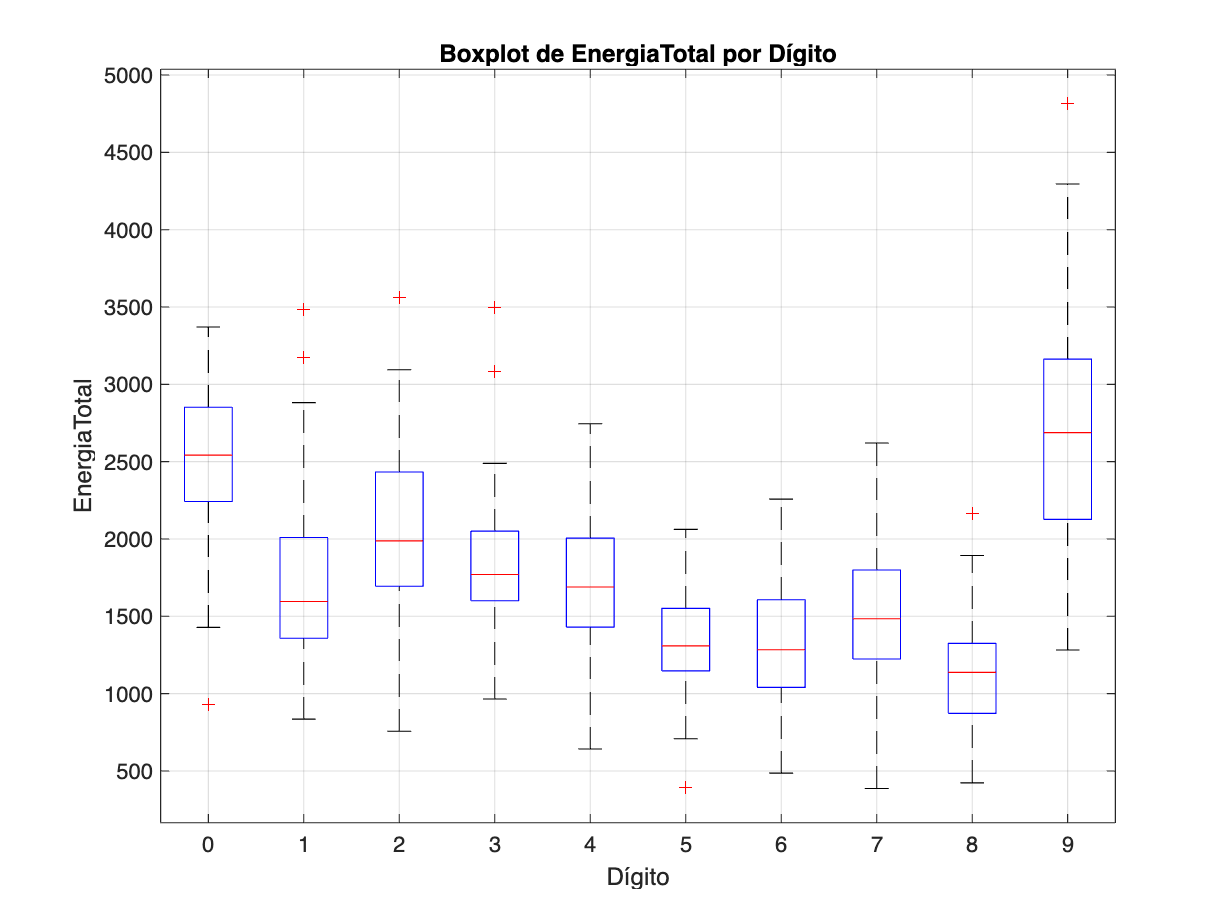

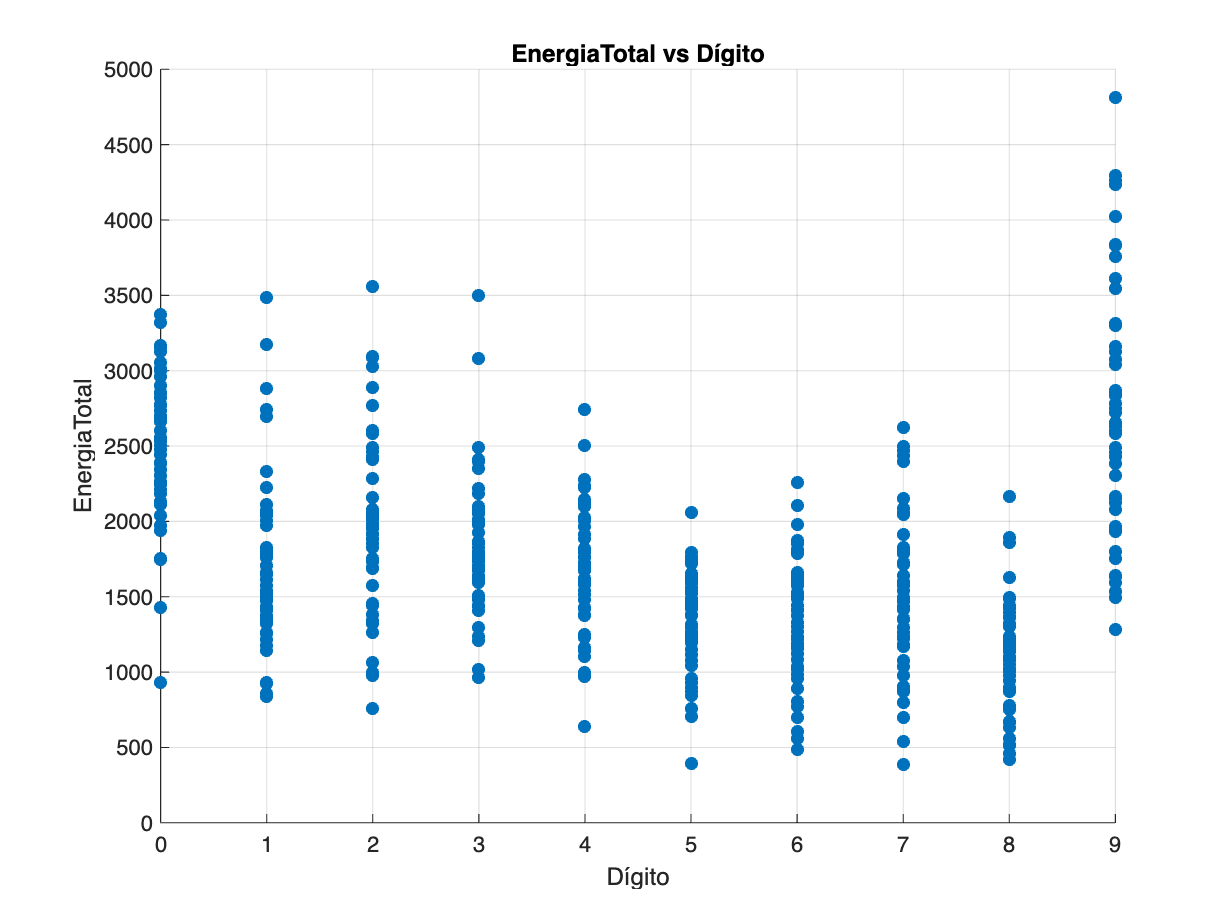

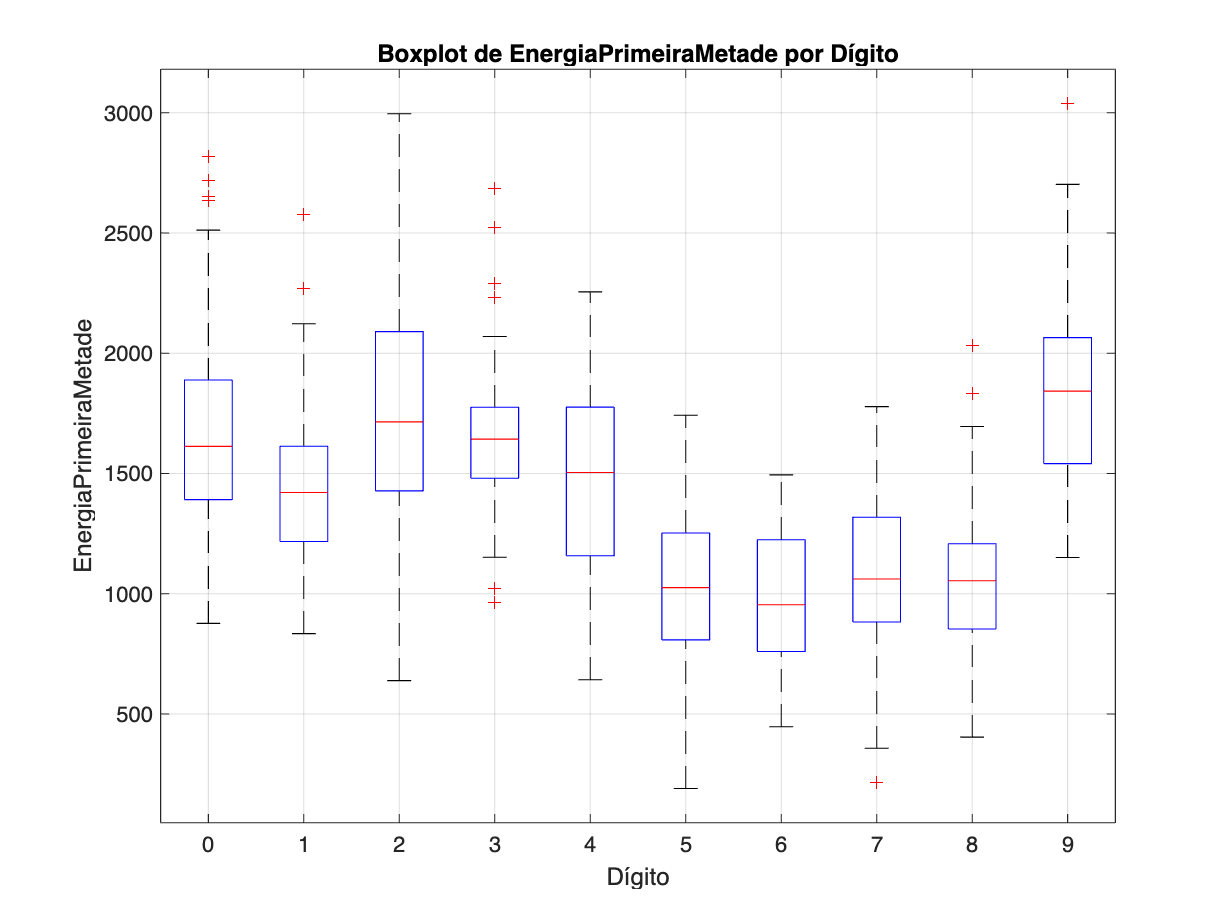

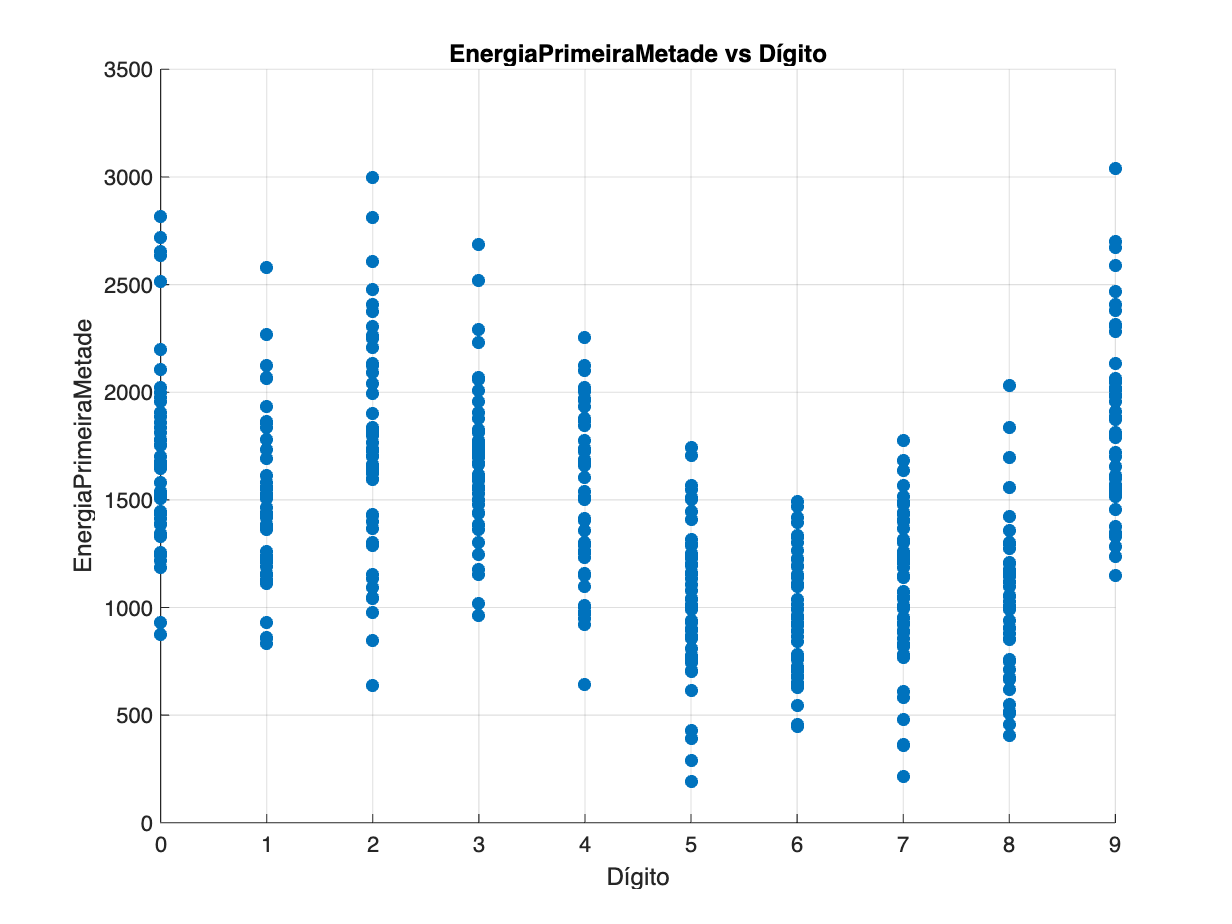

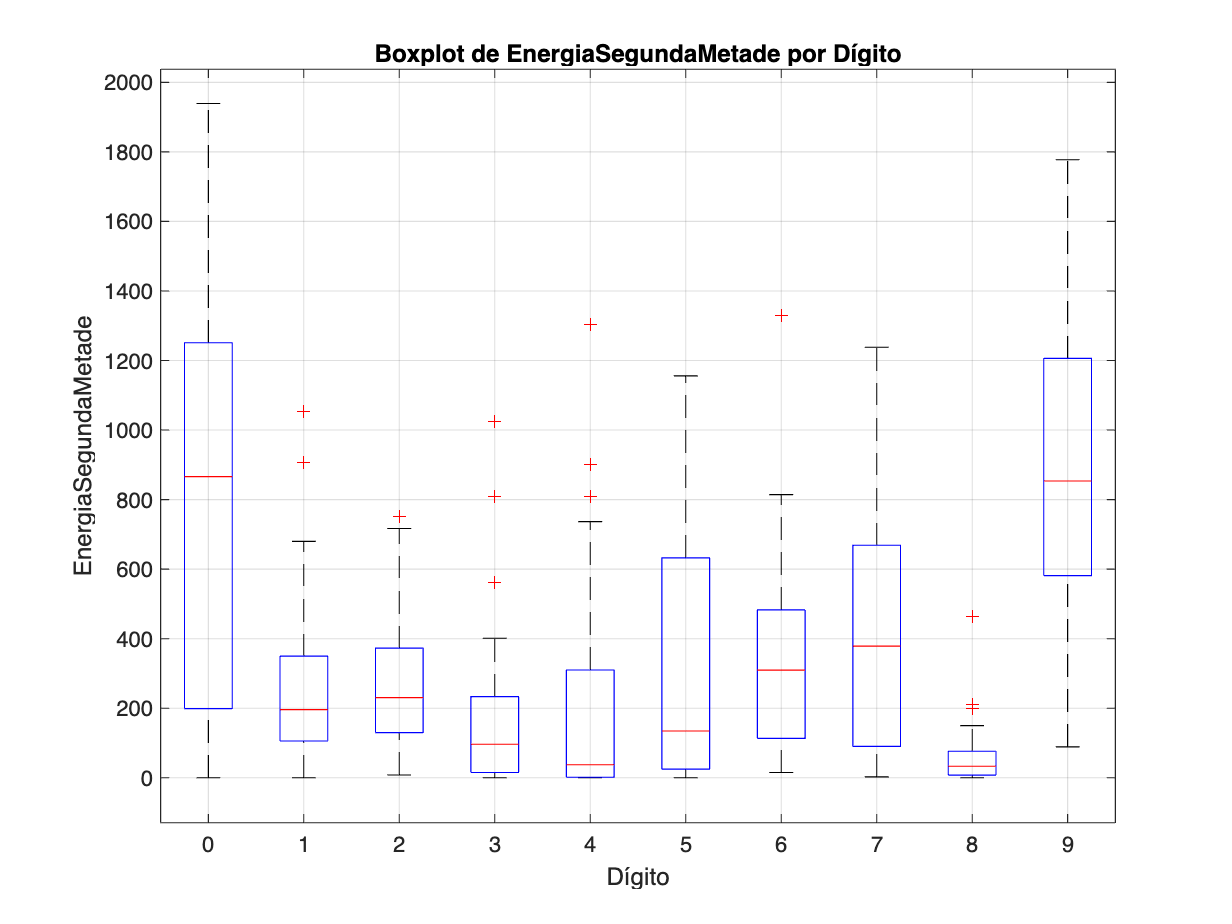

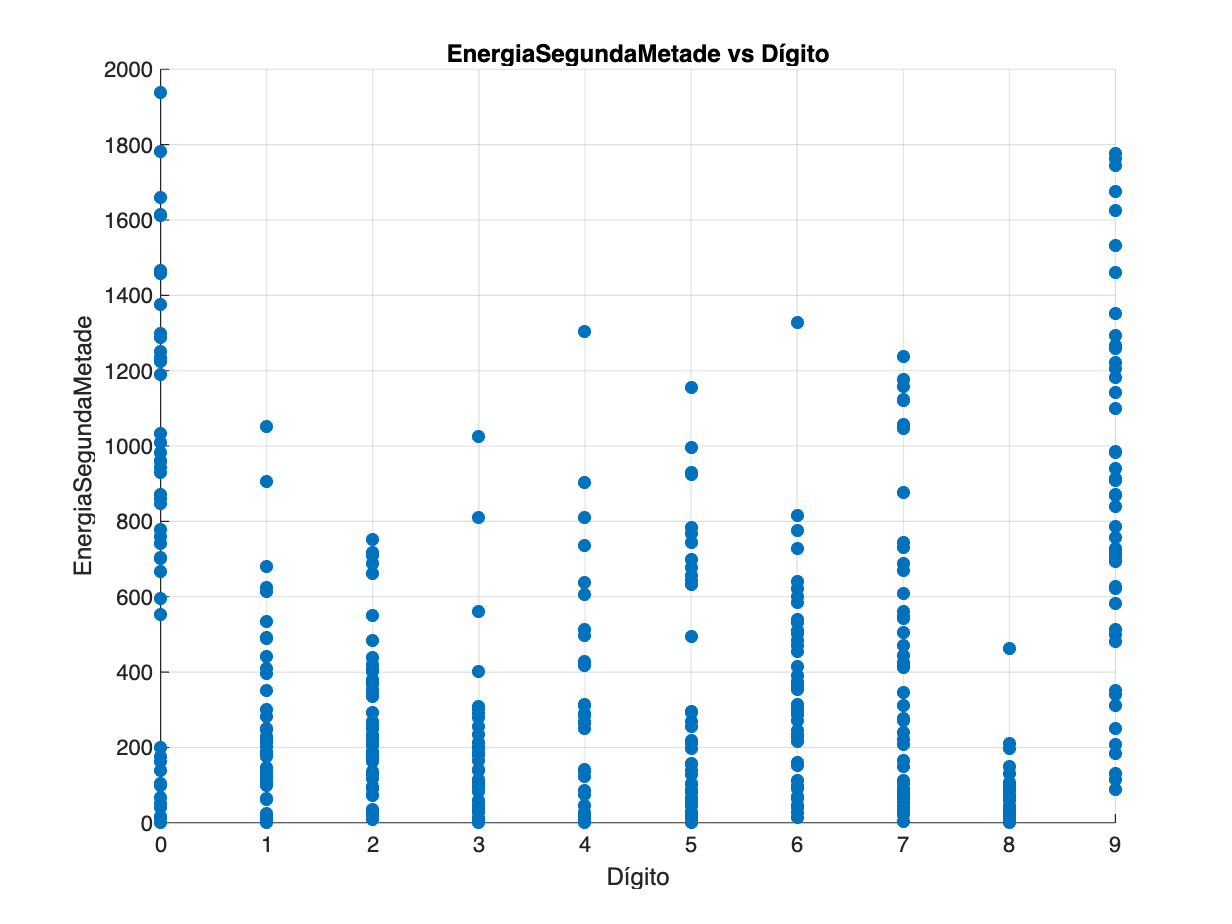

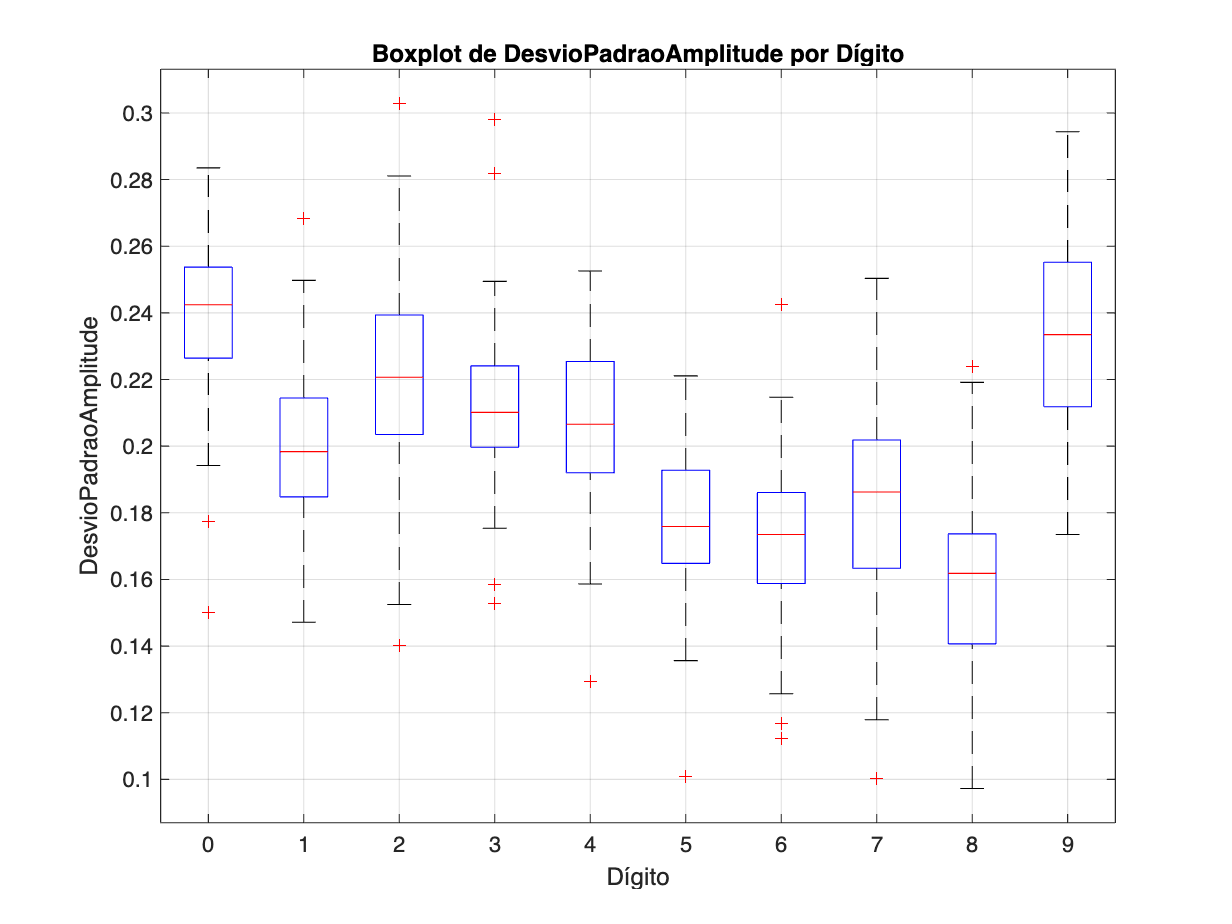

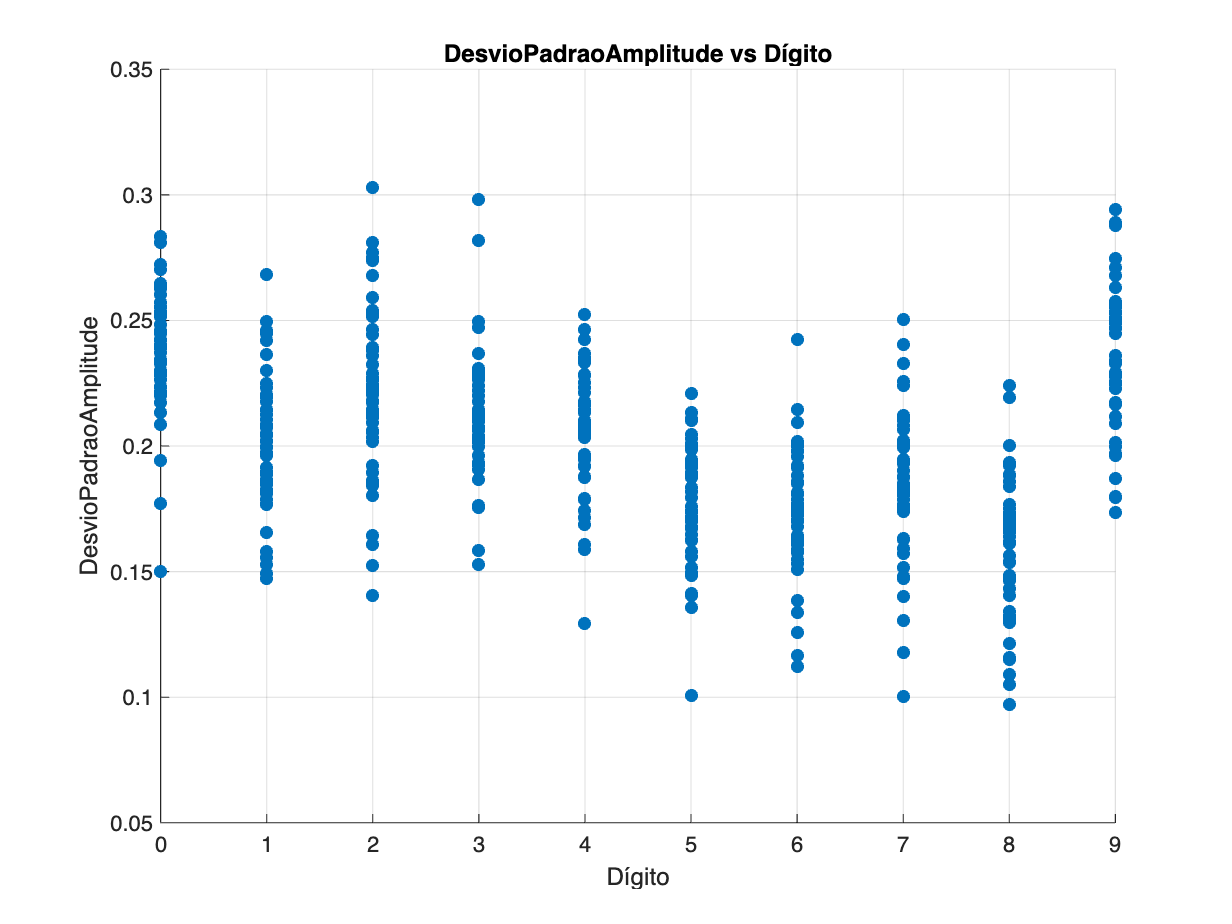


features = {'EnergiaTotal','EnergiaPrimeiraMetade','EnergiaSegundaMetade',...
    'DesvioPadraoAmplitude','RMS','MediaAmplitude','FatorCrest','TaxaCruzamento'};

for i = 1:length(features)
    feat = features{i};
    
    % Boxplot da característica por dígito
    figure('Name', sprintf('Boxplot - %s por Dígito', feat), 'NumberTitle','off');
    boxplot(tab.(feat), tab.Digito);
    xlabel('Dígito');
    ylabel(feat);
    title(sprintf('Boxplot de %s por Dígito', feat));
    grid on;
    
    % Gráfico de dispersão 2D: característica vs dígito
    figure('Name', sprintf('Dispersão 2D - %s por Dígito', feat), 'NumberTitle','off');
    scatter(tab.Digito, tab.(feat), 'filled');
    xlabel('Dígito');
    ylabel(feat);
    title(sprintf('%s vs Dígito', feat));
    grid on;
end

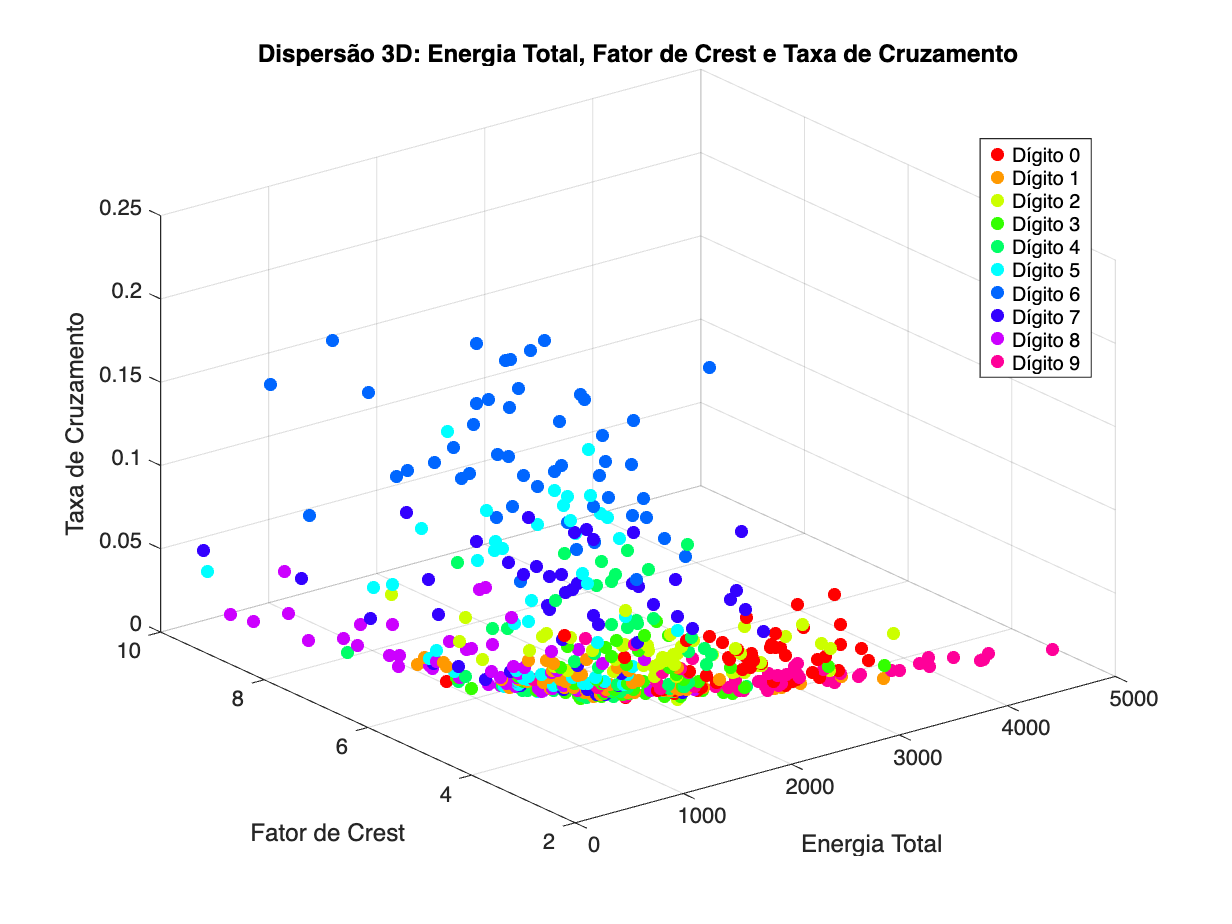


% Gráfico 3D para visualizar a relação entre Energia Total, Fator de Crest e Taxa de Cruzamento
digitosUnicos = unique(tab.Digito);
numDigitos = numel(digitosUnicos);
cores = hsv(numDigitos);
coresPontos = zeros(nArquivos,3);
for i = 1:nArquivos
    idx = find(digitosUnicos == tab.Digito(i));
    coresPontos(i,:) = cores(idx,:);
end

figure('Name','Dispersão 3D - Características Selecionadas','NumberTitle','off');
scatter3(tab.EnergiaTotal, tab.FatorCrest, tab.TaxaCruzamento, 36, coresPontos, 'filled');
xlabel('Energia Total');
ylabel('Fator de Crest');
zlabel('Taxa de Cruzamento');
title('Dispersão 3D: Energia Total, Fator de Crest e Taxa de Cruzamento');
grid on;
hold on;
dummyHandles = gobjects(numDigitos,1);
for i = 1:numDigitos
    dummyHandles(i) = scatter3(NaN, NaN, NaN, 36, cores(i,:), 'filled');
end
hold off;
entradasLegenda = arrayfun(@(d) sprintf('Dígito %d', d), digitosUnicos, 'UniformOutput', false);
legend(dummyHandles, entradasLegenda, 'Location','best');

## 9. Salvamento da Tabela Final

tab(:, {'Sinal_Raw', 'Taxa_Amostragem_Raw'}) = [];
save('AED1.mat', 'tab');
disp(tab);

                        Diretorio_Audio                         Nome_Arquivo      Digito    Participante    Repeticao    Sinal_Processado    Taxa_Amostragem    EnergiaTotal    EnergiaPrimeiraMetade    EnergiaSegundaMetade    DesvioPadraoAmplitude      RMS      MediaAmplitude    FatorCrest    TaxaCruzamento
    _______________________________________________________    _______________    ______    ____________    _________    ________________    _______________    ____________    _____________________    ____________________    _____________________    



%% Funções Auxiliares
function info = extrairInfoArquivo(nomeArquivo)
    % Remove a extensão e separa o nome utilizando '_' como delimitador
    [~, nomeSemExt, ~] = fileparts(nomeArquivo);
    partes = split(nomeSemExt, '_');
    if numel(partes) >= 3
        info.digito = str2double(partes{1});
        info.participante = str2double(partes{2});
        info.repeticao = str2double(partes{3});
    else
        warning('Formato inesperado: %s', nomeArquivo);
        info.digito = NaN;
        info.participante = NaN;
        info.repeticao = NaN;
    end
end

function s_proc = processarSinal(s, fs)
    % Remove o silêncio inicial com base em um limiar
    limiar = 0.02;
    idx = find(abs(s) > limiar, 1, 'first');
    if ~isempty(idx)
        s = s(idx:end);
    end
    
    % Normaliza o sinal para o intervalo [-1, 1]
    if max(s) ~= min(s)
        s = 2 * (s - min(s)) / (max(s) - min(s)) - 1;
    end
    
    % Ajusta a duração para 0.8 segundos (completa com zeros ou trunca)
    duracao_alvo = 0.8;
    num_amostras_alvo = round(duracao_alvo * fs);
    if length(s) < num_amostras_alvo
        s = [s; zeros(num_amostras_alvo - length(s), 1)];
    elseif length(s) > num_amostras_alvo
        s = s(1:num_amostras_alvo);
    end
    s_proc = s;
end




